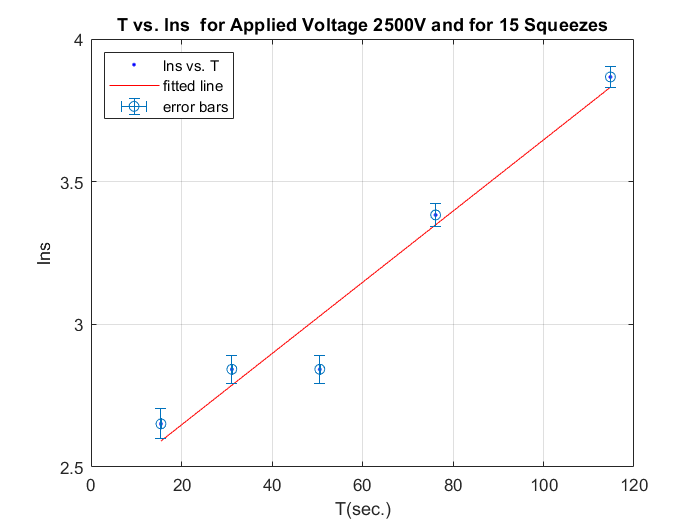

[xData, yData] = prepareCurveData( T2500_15, lns2500d15 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns2500d15 vs. T2500_15', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T(sec.)
ylabel lns
grid on

hold on

xerrorpos=[0.071 0.071 0.071 0.071 0.071];
xerrneg=xerrorpos;
errypos=[0.14/2.65112705370259 0.14/2.84258109405982 0.14/2.84258109405982 0.14/3.38337279674960 0.14/3.86702563949741];
erryneg=errypos;
errorbar(T2500_15,lns2500d15,erryneg,errypos,xerrneg,xerrorpos,'o');

title('T vs. lns  for Applied Voltage 2500V and for 15 Squeezes')

legend({'lns vs. T','fitted line','error bars'},'Location','northwest')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01221  (0.012, 0.01242)
  %     p2 =       2.461  (2.446, 2.475)

%Goodness of fit:
 % SSE: 8.074e-05
  %R-square: 0.9999
  %Adjusted R-square: 0.9999
 % RMSE: 0.005188